# t_wvfOverview

The performance of a shift-invariant optical system can be modeled by knowing its (wavelength-dependent) point spread function. ISETCam mainly uses a wavefront structure to represent the information in the point spread function.

The concept of the wavefront aberrations are not widely understood, and we introduce them to ISETCam users here. The wavefront aberration functions are related to the point spread function by a Fourier Transform.  We store the wavefront aberration information in the optics struct, which is part of the oi struct.  

The reliance on the wavefront aberrations has many advantages in specifying and controlling the lens properties in general.  It is particularly helpful for the ISETBio calculations because with the development of adaptive optics, the human eye is often characterized with respect to the wavefront aberrations. Tutorials about the human eye are in the ISETBio repository.

### Historical Notes

ISETCam could have stored the pointspread functions directly.  Doing so, however, introduces a challenge:  What sample spacing should we use to store the point spreads?  Should they be sampled at 1 micron? or 10 microns?  

An alternative to the point spread function is to store the optical transfer function (OTF), which is also related by Fourier Transform to the pointspread. ISETCam used this approach for many years, but it has the same sampling problem:  we must specify the frequency samples of the OTF in advance of any calculation, before we know the spatial sampling of the scene and the optical image.  For many years, we simply stored these functions at high resolution and that was sufficient. 

As part of our work on high dynamic range imaging, we realized that the sampling problem could be avoided if we have a continuous function to describe the point spread or the OTF.  In that case, we could create the correctly sampled function at the time of the calculation.  The wavefront aberration  has a natural, continuous  representation based on the Zernike polynomials.  These continuous functions are defined on the disk, and they efficiently represent the point spread of many types of lenses. The Zernike representation provides several intuitive parameters for controlling lens properties such as defocus and astigmatism.

A final advantage of using the wavefront representation is that it provides a simple means of representing the shape of the pupil.  Normally, we describe the pupil opening as circular.  In cases, however, the pupil is not circular.  The wavefront aberration representation has a straightforward means of incorporating the shape of non-circular pupil functions in the calculation. 

**See also - **

         wvfCompute, wvfGet, wvfSet, wvf2oi, wvf2optics, wvfPlot, wvfSummarize, wvf*

### Implementation

The wavefront parameters and their current defaults , implemented in wvfCreate, are:

This default wavefront corresponds to a diffraction-limited lens (ideal lens) with an f-number equal to the human eye (~5.7) for historical reasons. That is why the zcoeffs parameter (Zernike coefficients) is simply 0.

This tutorial illustrates the properties of the optics that is represented by the wavefront structure and its metadata. We discuss standard properties such as f-number and focal length. The oiCompute function uses the information in the wavefront structure to calculate the appropriately sampled point spread function for a given scene and optical image. We also discuss sample spacing in the psf plane. We show (at the end) how to create a PSF with specific spatial sampling separation.

## An image of the pupil plane

The wavefront aberrations are specified in the pupil plane.  We specify the full set of wavefront aberrations with respect to a pupil diameter.  This measured pupil might be 8 mm, say for a human eye with the pupil opened up wide.  From the Zernike polynomial, we can calculate the wavefront aberration over that reference sized disk.

During calculations, we sample the values of the wavefront aberrations in the pupil plane over a reference field size. By default this size is 16.212 mm (I don't know why this value).  This size has to be larger than the measured pupil diameter for the Fourier transforms to work out later.

The number of samples specifies the discretization over the pupil plane.  The field size and number of samples are always square.

Finally, we perform the calculation using a pupil that must be smaller than the measured pupil size (calc pupil diameter).  It can not be larger because, well, we don't know the aberrations over that size.  The figure below illustrates a measured and calculated pupil that are both circular.  It is possible in the software to specify pupil shapes that are non-circular, and even pupils that contain scratches and dust.

The functions wvfCompute() which calls wvfComputePupilFunction() and wvfComputePSF() read the wavefront aberration parameters to produce the point spread function (PSF) of the shift-invariant optics.

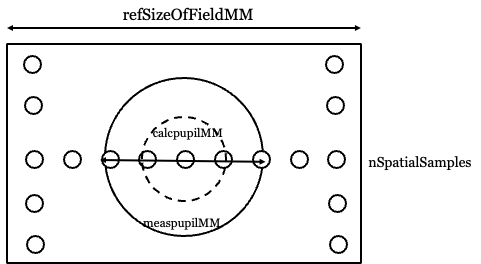

## Image plane

The wvf represents the number of microns per degree explicitly.  This parameter is used to infer the focal length.  The focal length and the calculated pupil diameter can be used to infer the f number or the numerical aperture (not yet implemented).

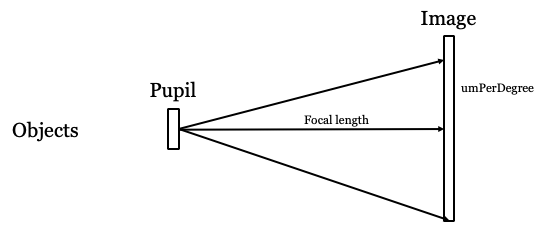

## The default wavefront

There are enough parameters with enough units that we felt the need to write a function to summarize them and their units.  Here is the default wavefront structure.  Notice that its parameters are similar to the human eye.

wvf = wvfCreate;
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


## Number of spatial samples

Changing the 'npixels' parameter changes the 'Max PSF support' but not the 'PSF dx (spacing)'. It changes the OTF spacing, but not the highest frequency for the OTF support.

wvf = wvfCreate;
wvf = wvfSet(wvf,'npixels',101);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 101
ref pupil plane	 16.212000	 mm
ref pupil dx	 160.514851	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 17.148651	 cyc/mm
Max PSF support	 29.156813	 um
PSF dx		 0.583136	 um
-------------------


wvf = wvfSet(wvf,'npixels',801);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 801
ref pupil plane	 16.212000	 mm
ref pupil dx	 20.239700	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 2.143581	 cyc/mm
Max PSF support	 233.254502	 um
PSF dx		 0.583136	 um
-------------------


## Focal length 

Changing the focal length is equivalent to changing um per degree.  Changing the focal length changes several other variables.  For example, it changes the f number, which is the ratio of the focal length and pupil diameter.  

The spacing and support of the PSF (Max PSF support) and OTF (Max OTF frequency) also change. See image plane figure above to get an intuition of why. When the focal length is small, the pixels in the pupil plane map into a high spatial density in the image plane.  Thus, the peak spatial frequency is also much higher.

wvf = wvfCreate;
wvf = wvfSet(wvf,'focal length',4,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 1.333333
f length	 4.000000	 mm
um per deg	 69.814942	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 3684.451923	 cyc/mm
OTF df		 36.844519	 cyc/mm
Max PSF support	 13.570539	 um
PSF dx		 0.135705	 um
-------------------


wvf = wvfSet(wvf,'focal length',40,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 13.333333
f length	 40.000000	 mm
um per deg	 698.149423	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 368.445192	 cyc/mm
OTF df		 3.684452	 cyc/mm
Max PSF support	 135.705394	 um
PSF dx		 1.357054	 um
-------------------


The graphs below illustrate the PSF change.  The PSF values are similar but the support and sample spacing changes dramatically between the two plots.  One is supported over only a litle more than 10 microns, and the other is supported over more than 100 um.

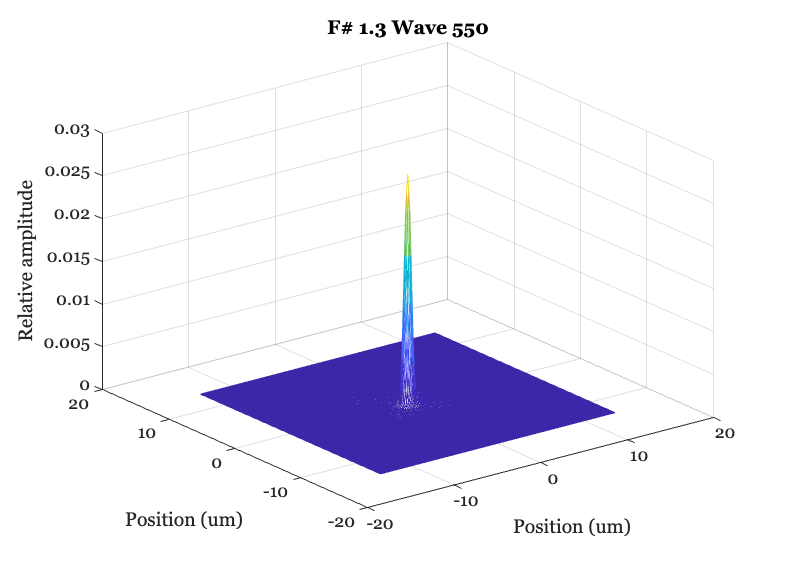

wvf = wvfSet(wvf,'focal length',4,'mm');
wvf = wvfCompute(wvf); 
wvfPlot(wvf,'psf','unit','um','plot range',15);

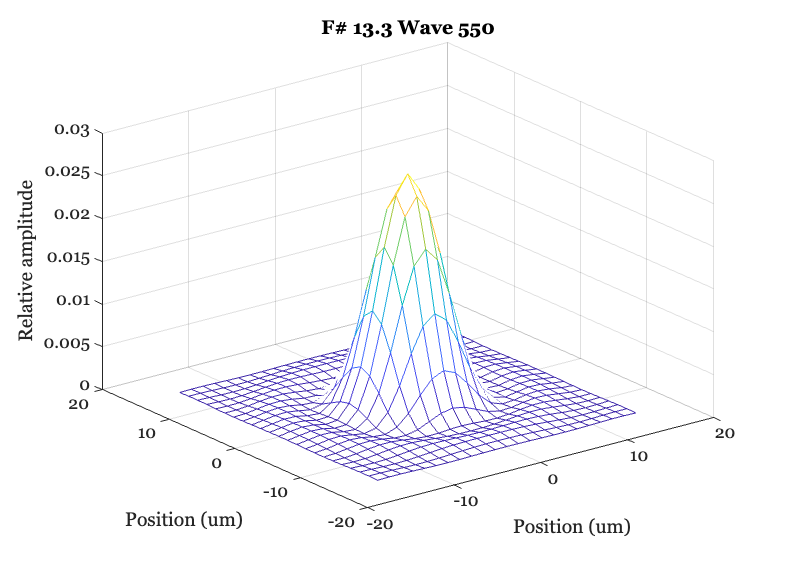

wvf = wvfSet(wvf,'focal length',40,'mm');
wvf = wvfCompute(wvf); 
wvfPlot(wvf,'psf','unit','um','plot range',15);

## Calc pupil diameter

This calculation pupil is used at the time we perform the oiCompute.  Changing its value does not change the PSF and OTF sampling parameters.

wvf = wvfCreate;
wvf = wvfSet(wvf,'calc pupil diameter',1,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 17.188300
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 1.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


This is the diffraction limited PSF for a 1 mm pupil, which is an f/# of 17.2

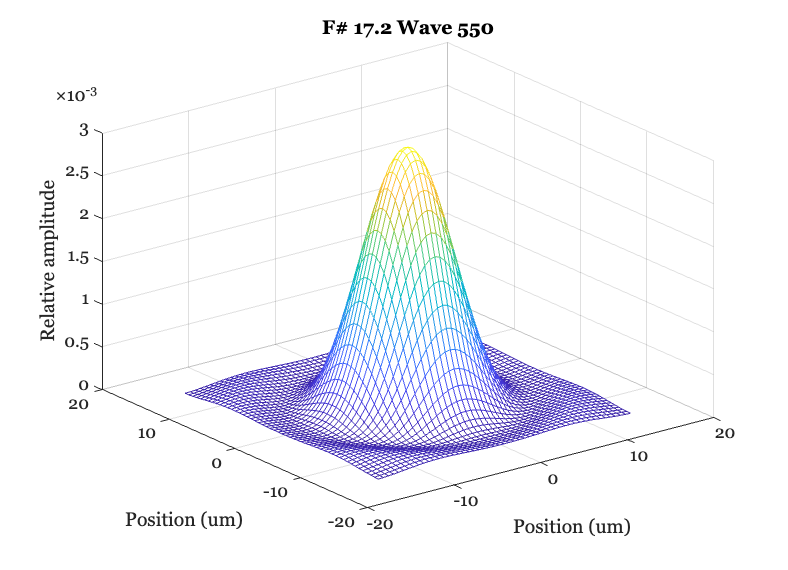

wvf = wvfCompute(wvf); 
wvfPlot(wvf,'psf','unit','um','plot range',15);

Notice that increasing the size of the pupil diameter changes the f/# to 2.9.  It does **not** change the sample values of the OTF or PSF.  The zCoeffs, zDiameter and OTF/PSF parameters are unchanged.  But the values of the PSF (and OTF) measured at those sample values does change. As the pupil opens up, the diffraction limted PSF gets mch smaller.  Notice that the PSF sample positions is unchanged.

wvf = wvfSet(wvf,'calc pupil diameter',6,'mm');
wvf = wvfCompute(wvf);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 2.864717
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 6.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


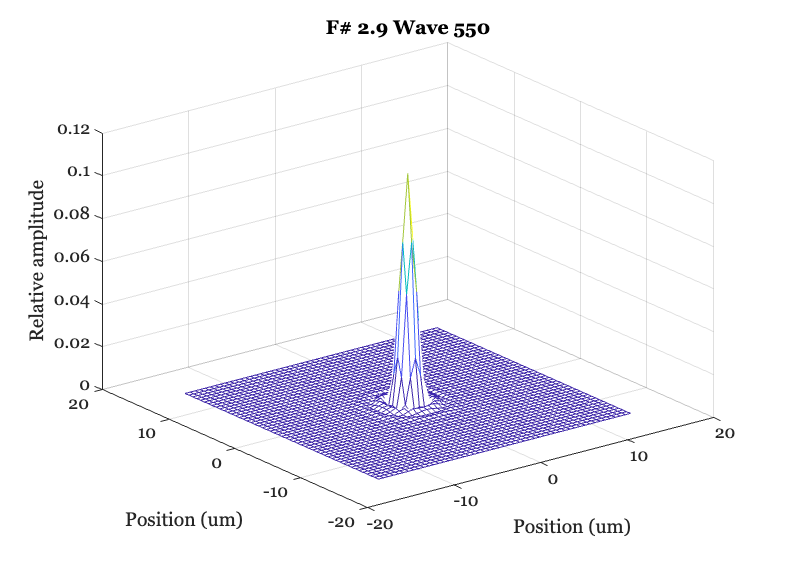

wvfPlot(wvf,'psf','unit','um','plot range',15);

## Change the measured pupil specification

For a diffraction limited case, when the zcoefs are simply the scalar value of 0, changing the measured pupil is irrelevant.  If we made it bigger or smaller, we would still be diffraction limited and only the size of the  pupil for calculation matters.

wvf = wvfCreate;
wvf = wvfSet(wvf,'measured pupil diameter',1,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 1.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


wvf = wvfSet(wvf,'measured pupil diameter',6,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 6.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


The following to plots show that the PSF is unchanged because the calc pupil diameter is unchanged.

wvf = wvfSet(wvf,'measured pupil diameter',1,'mm');
wvf = wvfSet(wvf,'calc pupil diameter',1,'mm');
wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

wvf = wvfSet(wvf,'measured pupil diameter',6,'mm');
wvf = wvfSet(wvf,'calc pupil diameter',1,'mm');
wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

## Match a target OI sample spacing

This next section analyzes how we control the PSF sample spacing.  We often want to do this so we can create an OI image that matches the spatial sampling of the sensor pixels.  The key is to adjust the field size, or a combination of the reference field size and the number of spatial samples in the field.  (I think).

lambdaMM = 550e-6;
fnumber = 4;
focallengthMM = 4;
nPixels = 1024;

wvf = wvfSet(wvf, 'focal length', focallengthMM, 'mm');
wvf = wvfSet(wvf, 'calc pupil diameter', focallengthMM/fnumber);
wvf = wvfSet(wvf, 'spatial samples', nPixels);

% this is what we are trying to match
psf_spacingMM = 1e-3; 

% compute the pupil sample spacing that matches this PSF sample
% spacing in the image plane.
pupil_spacingMM = lambdaMM * focallengthMM / (psf_spacingMM * nPixels);

wvf = wvfSet(wvf,'field size mm', pupil_spacingMM * nPixels);

The PSF spacing is about 1 micron after these sets.

wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 4.000000
f length	 4.000000	 mm
um per deg	 69.814942	 um
calc pupil diam	 1.000000	 mm

Reference
------
n samples	 1024
ref pupil plane	 2.200000	 mm
ref pupil dx	 2.148438	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 6.000000	 mm
Max OTF freq	 499.010770	 cyc/mm
OTF df		 0.976538	 cyc/mm
Max PSF support	 511.012972	 um
PSF dx		 1.000025	 um
-------------------


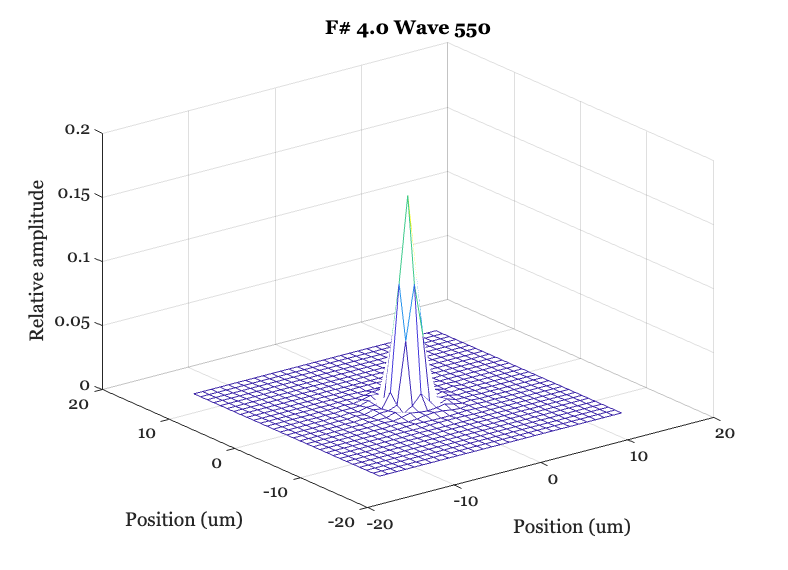

wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

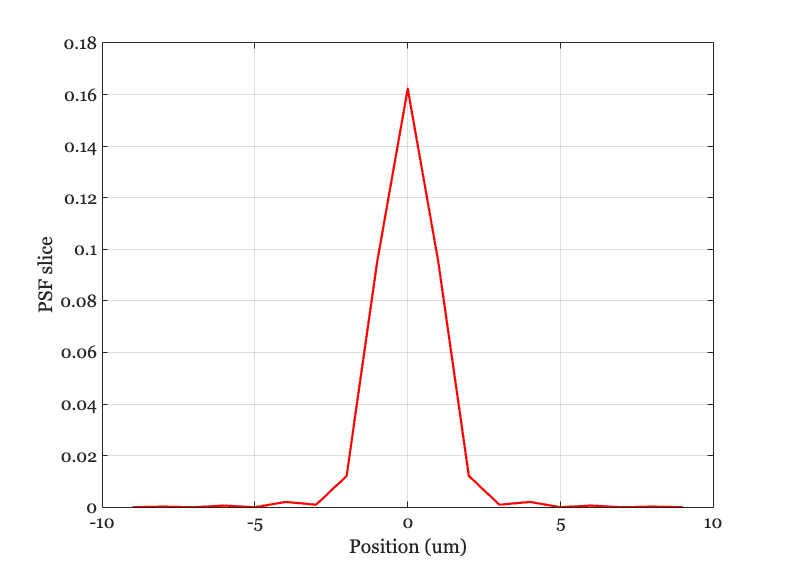

wvfPlot(wvf, '1d psf space', 'unit', 'um','plot range',10);

Notice that these settings made the pupil plane just 2.2 mm.  This value is smaller than many pupil diameter cases.  That should be avoided.

Here we set the psf spacing to 2 microns. The PSF is the same spread, except coarsely sampled.

psf_spacingMM = 2e-3; 
pupil_spacingMM = lambdaMM * focallengthMM / (psf_spacingMM * nPixels);
wvf = wvfSet(wvf,'field size mm', pupil_spacingMM * nPixels);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 4.000000
f length	 4.000000	 mm
um per deg	 69.814942	 um
calc pupil diam	 1.000000	 mm

Reference
------
n samples	 1024
ref pupil plane	 1.100000	 mm
ref pupil dx	 1.074219	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 6.000000	 mm
Max OTF freq	 249.505385	 cyc/mm
OTF df		 0.488269	 cyc/mm
Max PSF support	 1022.025944	 um
PSF dx		 2.000051	 um
-------------------


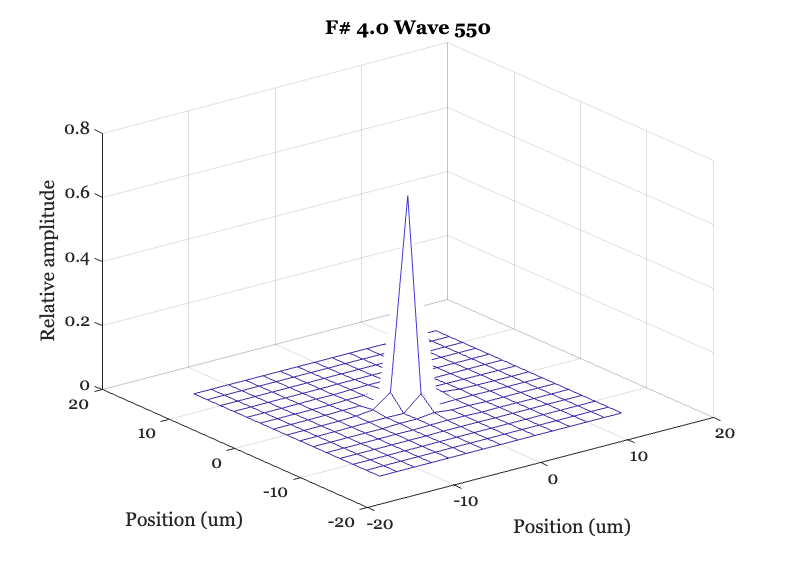

wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

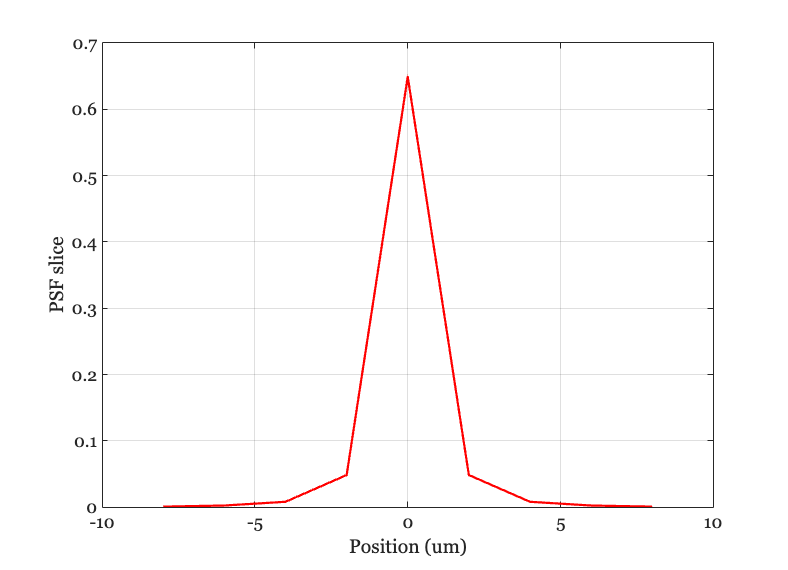

wvfPlot(wvf, '1d psf space', 'unit', 'um','plot range',10);

## Other parameters 

The Stiles-Crawford effect (SCE) and some other parameters are not discussed here.  They will be described in the scripts and other calculations.

- sce

- measObserverAcommodationDiopters - 0

- constantSampleIntervalDomain - 'psf'

- conePsfInfo